### 1.

clear all; clc; close all;
dcl_init;
modulation = 'psk';             
k = 1;                          % Bit Per Symbol
M = 2^k;  
rng(1);
pkt_size = 1e5;
b_tx = bit_gen(pkt_size, k)

b_tx =      0
     1
     0
     0
     0
     0
     0
     0
     0
     1


### 2.

flg_gray_encode = 1

flg_gray_encode = 1

if(flg_gray_encode == 1)
    b_code = gray_code(k)    
else
    b_code = non_code(k) 
end 

b_code =      0
     1



sym_idx = zeros(size(b_tx,1),1);
for i=1:size(b_tx,1)
    sym_idx(i,1) = find(sum(b_code == b_tx(i,:),2) == k);
end
sym_idx

sym_idx =      1
     2
     1
     1
     1
     1
     1
     1
     1
     2


[cons, Es_avg] = constellation(M, modulation)

cons =    1.0000 + 0.0000i
  -1.0000 + 0.0000i


Es_avg = 1

mod_sym = zeros(size(sym_idx));
for i=1:size(sym_idx,1)
    mod_sym(i,1) = cons(sym_idx(i,1));
end
mod_sym

mod_sym =    1.0000 + 0.0000i
  -1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
  -1.0000 + 0.0000i


### 3

pulse_shape_mode = 'kron'

pulse_shape_mode = 'kron'

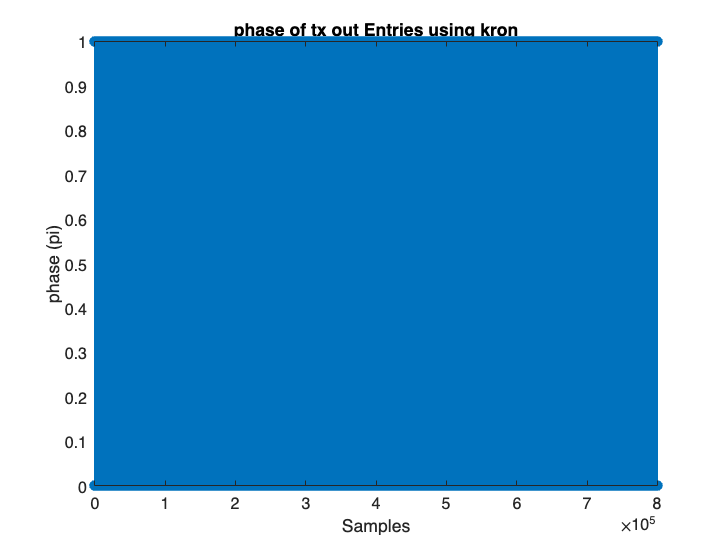

[tx_smpl, cons] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_shape_mode);
stem(angle(tx_smpl)/pi, 'filled')
title('phase of tx out Entries using kron')
xlabel('Samples')
ylabel('phase (pi)')

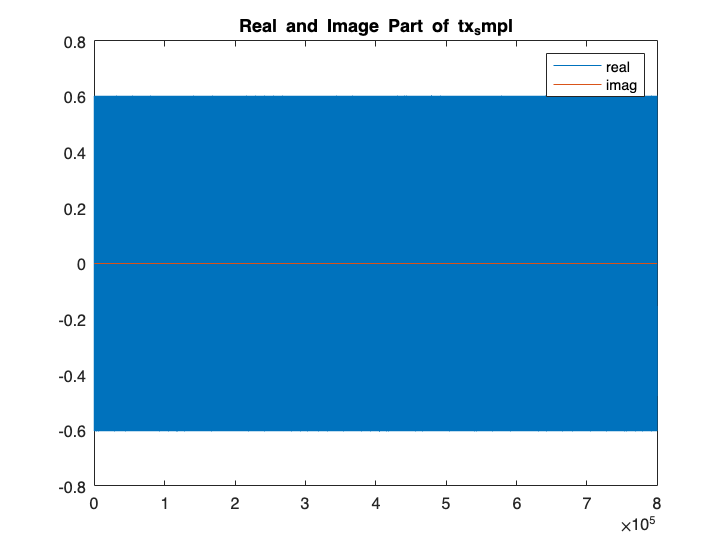


plot([real(tx_smpl), imag(tx_smpl)])
title('Real and Image Part of tx_smpl')
legend('real','imag')

pulse_shape_mode = 'conv'

pulse_shape_mode = 'conv'

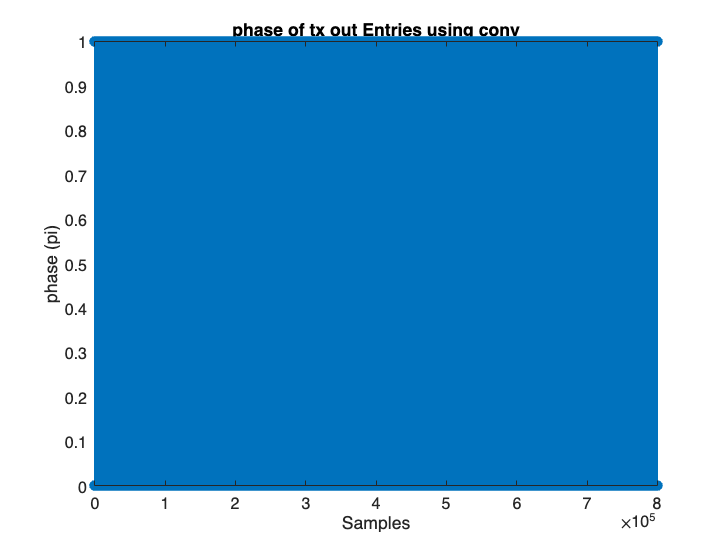

[tx_smpl, cons] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_shape_mode);
stem(angle(tx_smpl)/pi, 'filled')
title('phase of tx out Entries using conv')
xlabel('Samples')
ylabel('phase (pi)')

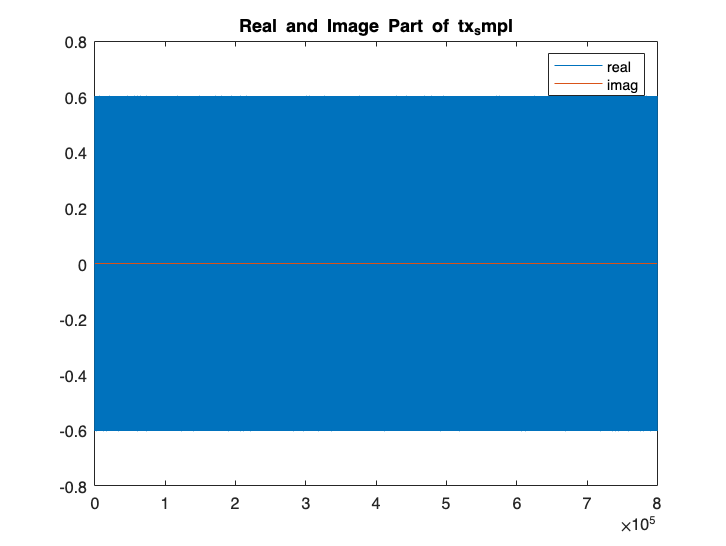


plot([real(tx_smpl), imag(tx_smpl)])
title('Real and Image Part of tx_smpl')
legend('real','imag')

tx_smpl_delayed = [zeros(chnl_delay_in_smpl,1); tx_smpl];
rx_smpl = tx_smpl_delayed .* exp(1i*chnl_phase_offset);

Eb =  Es_avg/log2(M) 

Eb = 1

EbNo = db2pow(snr_max)

EbNo = 10

var_noise = (Eb ./ EbNo)

var_noise = 0.1000

mean_noise = 0

mean_noise = 0

noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1i * randn(size(rx_smpl))) + mean_noise

noise_smpl =   -0.1219 - 0.1471i
   0.0846 + 0.2228i
  -0.0732 - 0.1378i
  -0.1206 - 0.1221i
   0.2417 - 0.2470i
   0.2251 - 0.3072i
   0.1139 - 0.0954i
  -0.4696 + 0.3696i
  -0.0031 - 0.1117i
  -0.0537 - 0.0266i


rx_smpl_noise = rx_smpl + noise_smpl

rx_smpl_noise =   -0.1219 - 0.1471i
   0.2354 + 0.2228i
   0.2283 - 0.1378i
   0.3317 - 0.1221i
   0.8448 - 0.2470i
   0.6774 - 0.3072i
   0.4154 - 0.0954i
  -0.3189 + 0.3696i
  -0.0031 - 0.1117i
  -0.2044 - 0.0266i


rx_smpl_eq = rx_smpl_noise(chnl_delay_in_smpl + 1 : end);
modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode

modulation = 'psk'

M = 2

fs = 3.8333e+14

smpl_per_symbl = 8

pulse_name = 'triangular'

rx_mode = 'matched_filter'

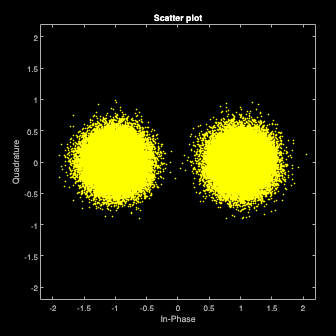

[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_eq, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
scatterplot((rx_sym))

det_bit = b_code(det_sym_idx,:)

det_bit =      0
     1
     0
     0
     0
     0
     0
     0
     0
     1


ser = sum(det_sym_idx ~= sym_idx)/length(sym_idx)

ser = 1.0000e-05

ber = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2))

ber = 1.0000e-05

serPSK = zeros(size(snr_db));
berPSK = zeros(size(snr_db));
for i = 0:1:10
    Eb =  Es_avg/log2(M);
    EbNo = db2pow(i);
    var_noise = (Eb ./ EbNo);
    mean_noise = 0;
    noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1i * randn(size(rx_smpl))) + mean_noise;
    rx_smpl_noise = rx_smpl + noise_smpl;
    rx_smpl_eq = rx_smpl_noise(chnl_delay_in_smpl + 1 : end);
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_eq, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
    det_bit = b_code(det_sym_idx,:);
    serPSK(i + 1) = sum(det_sym_idx ~= sym_idx)/length(sym_idx);
    berPSK(i + 1) = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2));
end


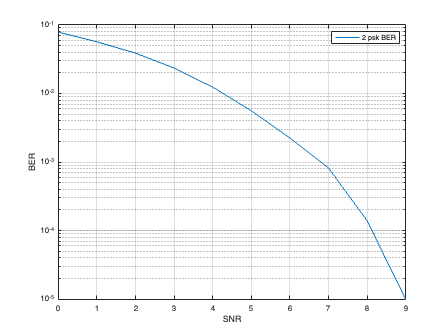

figure
semilogy(snr_db,berPSK)
ylabel('BER')
xlabel('SNR')
legend(sprintf('%d %s BER',M,modulation))
grid on